## TOPIC 5: Conditionals and Boolean Operators

ENGR105, 9/17/20

#### Loops (continued): for and while loops

As a reminder, `for` loops enable us to repeat tasks for a fixed number of iterations. In the example last time, we used a `for` loop to create a vector containing the first 10 elements of the Fibonacci sequence.

% Populate an array containing the first ten numbers of the sequence.
n = 10;
% Empty the vector x - we used it previously
x = [];
x(1) = 0;
x(2) = 1;
% Create each subsequent entry by taking the sum of the previous two
% entries
for k = 3:n
	x(k) = x(k-1) + x(k-2);
end
% Display the vector
disp(x)

     0     1     1     2     3     5     8    13    21    34



On the other hand, `while` loops are a type of iteration in which a sequence of instructions may be repeated while some condition is true. Last time, we used a `while` loop to create a vector containing all elements of the Fibonacci sequence less than 100.

% Max value of entries in Fibonacci sequence
n = 100;
% Define first two entries
x(1) = 0;
x(2) = 1;
% Iterate as long as the last element is less than 100.
while x(end) < n
    % If the last element is less that 100, add the next element of the
    % Fibonacci sequence to the vector
	x(end+1)=x(end)+x(end-1);
end
x(end)=[];  % Remove last element
disp(x)

     0     1     1     2     3     5     8    13    21    34    55    89



#### Vector preallocation

Preallocation is the process of creating a data structure (e.g. a vector) of final size (usually padded with zeros) before modifying the contents. This reduces the computational time by eliminating the operations associated with resizing the array. 

**Preallocation is a best practice to use whenever possible -- it is important if you use a **`for`** loop to populate a vector.**

Consider the Fibonacci sequence example using the `for` loop, in which we populated a vector with the first 10 entries of the Fibonacci sequence.

Let's calculate the time required to produce this Fibonacci vector of *differing lengths, with* and *without* preallocation.

To perform this analysis, we are going to:

- For sequence length, we will determine the time required to calculate the Fibonacci sequence, with and without preallocation

- Repeat with a greater number of Fibonacci elements.

- Plot *sequence (vector) length* vs. *computation time*.

% Define vector containing the number of entries in each successive
% Fibonacci vector.
N = round(logspace(0,8,20))

N =            1           3           7          18          48         127         336         886        2336        6158       16238       42813      112884      297635      784760     2069138     5455595    14384499    37926902   100000000


% Preallocate vectors to store time information
t_no = zeros(1,length(N));
t_yes = zeros(1,length(N));

% Calculate the time for each vector of length N(m)
for m = 1:length(N)
    
    % Calculate Fibonacci sequence vector without preallocation
    x = [];
    tic
    % Define first two entries
    x(1) = 0;
    x(2) = 1;
    % Create each subsequent entry by taking the sum of the previous two
    % entries
    for k = 3:N(m)
    	x(k) = x(k-1) + x(k-2);
    end
    t_no(m) = toc;
    
    % Calculate Fibonacci sequence vector with preallocation
    tic;
    x = zeros(1,N(m));
    % Define first two entries
    x(1) = 0;
    x(2) = 1;
    % Create each subsequent entry by taking the sum of the previous two
    % entries
    for k = 3:N(m)
    	x(k) = x(k-1) + x(k-2);
    end
    t_yes(m) = toc;
end

Plotting the above simulation results. Note the addtions to the code to produce a more professional plot. We will discuss plotting in detail later in the semester.

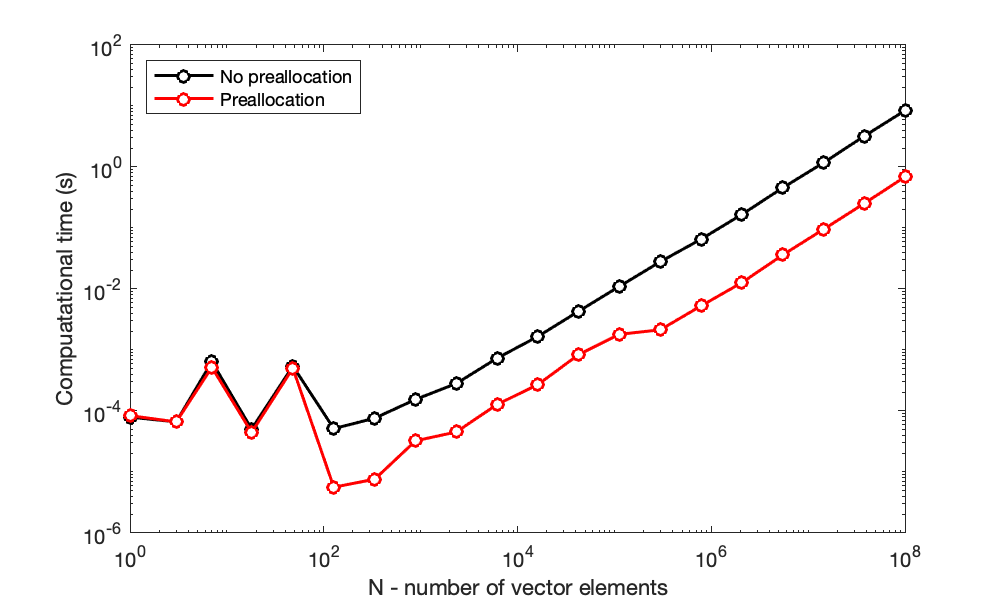

% Define dimensions of plot
figure('Position',[0,0,500,300]);
% Plot the functions
plot(N,t_no,'ko-',N,t_yes,'ro-','LineWidth',1.5,'MarkerFaceColor','auto')
% Graphical parameters
set(gca, 'XScale', 'log')   % "log" axes - x
set(gca, 'YScale', 'log')   % "log" axes - y
set(gca,'XMinorTick','on')
xlim([10^0,10^8]);  % range of x values on plot
ylim([10^-6,10^2]); % range of y values on plot
xlabel('N - number of vector elements');
ylabel('Compuatational time (s)');
legend('No preallocation','Preallocation','Location','northwest')

**Major takeaway**: you can save an **order of magnitude** of computational time using **preallocation**. 

#### For loops vs. vectorization

As described above, loops can be very useful for repeating many tasks a known or unknown number of times. In the case of for loops, we performed examples that could also be accomplished with vectorization, *i.e.* operating on a vector. Which of these approaches is better? To evaluate this, let's compare the computational time for each.

Specifically, let's calculate `b(k) = a(k)*a(k)`, where `a` is some vector. That is, we want to create a vector `b` in which each entry in the vector is the square of the corresponding entry in the vector `a`.

**1) Using a **`for`** loop.**

**2) Vectorization (e.g. using an element-wise operation)**

To perform this analysis, we are going to:

- Create a vector of a known length.

- Calculate the time required to perform the above operation on that vector using either a for loop or with vectorization.

- Repeat with a longer vector.

- Plot *vector length* vs. *computation time*.

% Define vector containing number of entries in potential vector.
N = round(logspace(0,8,20))

N =            1           3           7          18          48         127         336         886        2336        6158       16238       42813      112884      297635      784760     2069138     5455595    14384499    37926902   100000000


% Preallocate vectors to store information
t_for = zeros(1,length(N));
t_vec = zeros(1,length(N));

% Calculate the time for each vector of length N(m)
for m = 1:length(N)
    % Create vector of random numbers with dimension 1xN(m)
    a = rand(1,N(m));
    
    % Calculate time for for loop
    tic
    % Preallocate for loop vector
    b_for = zeros(1,N(m));
    % Calculate each entry in b by looping through all of vector a
    for n = 1:N(m)
        b_for(n) = a(n)^2;
    end
    t_for(m) = toc;
    
    % Calculate time for vectorization
    tic
    % Calculate all entries in b by element-wise exponentiation
    b_vec = a.^2;
    t_vec(m) = toc;
    
    % Clear b vectors for next iteration
    clear b_for b_vec
end

Plotting the above simulation results. Note the addtions to the code to produce a more professional plot. We will discuss plotting in detail later in the semester.

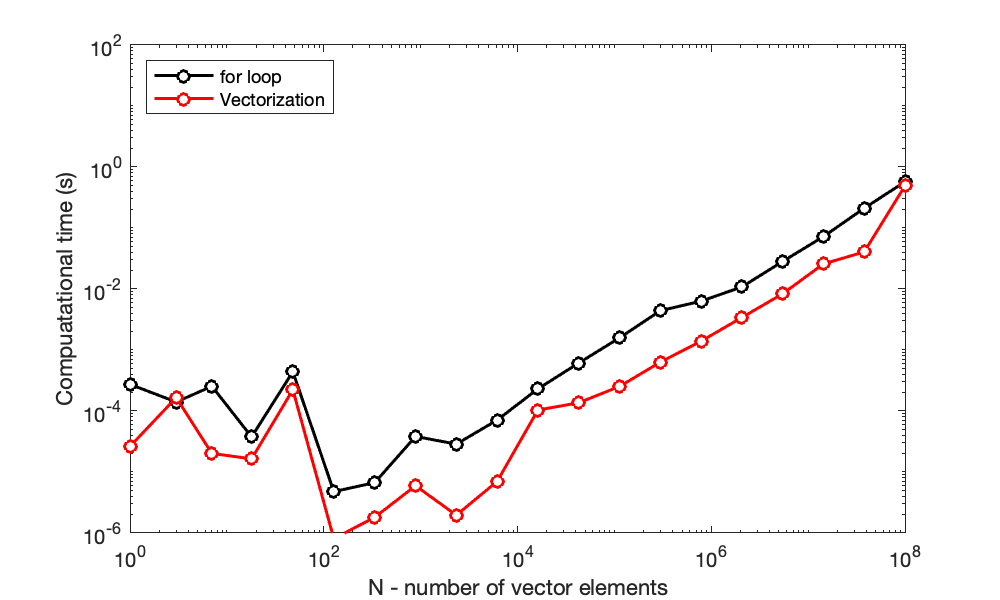

% Define dimensions of plot
figure('Position',[0,0,500,300]);
% Plot call and graphical commands
plot(N,t_for,'ko-',N,t_vec,'ro-','LineWidth',1.5,'MarkerFaceColor','auto')
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
set(gca,'XMinorTick','on')
xlim([10^0,10^8]);
ylim([10^-6,10^2]);
xlabel('N - number of vector elements');
ylabel('Compuatational time (s)');
legend('for loop','Vectorization','Location','northwest')

**Major takeaway**: you can save an **order of magnitude** of computational time using **vectorization** rather than a for loop (even with preallocation!).

**Remember**: we want code that is correct, clear, and computationally efficient.

#### Recall: while loops iterate as long as a logical condition is true

Loops can be used to repeat statements of code either for a defined number of iterations (as in a `for` loop) or as long as a logical condition is met (as in a `while` loop). In the case of while loops, below, the logical condition can be any relational or logical operation that equates to `true`. When the logical condition is no longer true, the loop ends.

Another potentially useful programming tool that makes use of a `<logical condition>` is the **conditional statement**, also known as an `if/then` statement or a **decision**.

### Conditional statements

Much of programming is focused on conditionals – the concept of *if this*…then *do that*. A visual representation of a conditional statement is shown below, in which conditional code is only carried out if a logical condition is true.

###             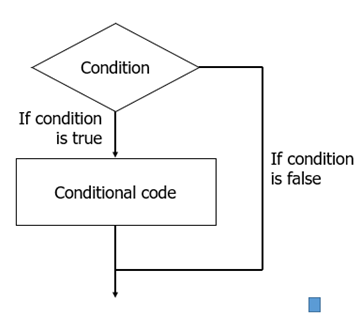

#### Anatomy of a simple `if` statement

In MATLAB, conditional statements have the following form.

- The `if` command indicates that the `<statements>` that follow should only be executed if the logical condition is `true`.

- The `<logical condition>` is any statement that evaluates to a logical result.

- Statements included after the `if` command will execute if the `<logical condition>` is `true`.

- The `end` statement indicates the termination point of any statements that should be executed if the `<logical condition>` is true

**Example**. Establish a variable with a value and overwrite the value if some statement is true.

a = 20;
% The output of b is first established as NaN (nothing special about this
% choice)
b = NaN; % "not a number"
 
if a >10
    %b would be displayed if the condition is met
    b = 25;
end


disp(b)

    25



**Example**. Evaluate the sum of a vector to determine if a variable should change value

% Declare vector and variable to store a value
v = [1, 5, 3];
res = 5;

% Overwrite a variable if the condition is true
if sum(v)>10
    res = 25;
end

disp(res)

     5



**Note**: Conditional statements must be one-sided – MATLAB will only evaluate the first relational operator of a series or bounded set of logical expressions

var1 = 40;
var2 = 12;
 
if 10 <var1<30
    var2 = 2*var2;
end

disp(var2)

    24



#### Nested `if `statements

`if` statements, like `for`and `while` loops, can be nested. An `end` statement is needed for each `if` statement

p = 6;
q = 15;
res = NaN;

% If condition one is true, "enter" the first if statement

if p>5
    if q ==15
        res = p*q
    end
end

res = 90

disp(res)

    90



**Note**: each instance of an `if` statement and the statements within are indented, just like with loops and function.

#### Anatomy of an `if-elseif-else` statement

More complex sets of conditions can be evaluated using the `if`-`elseif`-`else` construction

- Both the `if `and `elseif `statements require a separate `<logical condition>.`

- The `else `statement is a catch all and should not include a `<logical condition>`. If the `<logical condition>` associated with the `if` statement and all `elseif` statements equate to `false`, then the code following the `else` statement will execute.

A visual representation for an `if-elseif-else` statement can be seen below. This visual representation is known as a **decision tree**.

        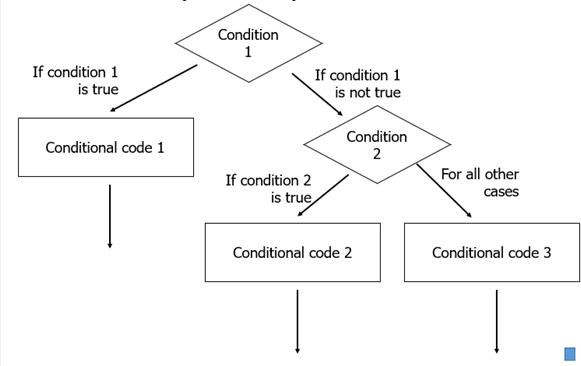

**Note**: there can be many `elseif` statements in an if statement, though they are not required. 

**Example**. `if-elseif-else` statement for one of my typical mornings.

**Example**. "Catching" one condition with `if` and all other conditions with `else.`

var1 = 1;
var2 = 2;

% "If var1 equals var2, then assign "true" to out. Otherwise, assign
% "false" to out.

if var1 == var2
    out = true;
else 
    out = false;
end
disp(out)

   0



Note: this code is demonstrational. The same output can be achieved using the single expression:

out = var1==var2;
disp(out)

   0



**Example**. Assign value to variable based on input variable.

% Classic problem: if my cereal is bad, the solution is clearly to add
% chocolate to it.
cerealGrade = 95;

if cerealGrade < 60
    chocolateAdded = 20;
elseif cerealGrade < 70
    chocolateAdded = 15;
elseif cerealGrade < 80
    chocolateAdded = 10;
elseif cerealGrade  <90
    chocolateAdded = 5;
else
    chocolateAdded = 0;
end
disp([cerealGrade,chocolateAdded])

    95     0



**Note**: The decision statement will terminate after the first condition is met. If computing with large data sets, catch the most common decision with the first `if` statement when possible.

The above code can be made more compact (*and easier to read*) so that it does not require the use of the `else` statement.

cerealGrade = 95;
chocolateAdded = 0;
%reduces the amoung of code becasue the end statement does not need to be
%included 

if cerealGrade < 60
    chocolateAdded = 20;
elseif cerealGrade < 70
    chocolateAdded = 15;
elseif cerealGrade < 80
    chocolateAdded = 10;
elseif cerealGrade  <90
    chocolateAdded = 5;
end
disp([cerealGrade,chocolateAdded])

    95     0



In the above, `chocolateAdded` is assigned a value of `0` before the decision and is only overwritten if one of the `if` or `elseif` statements reads `true`.

### Boolean operators

Boolean (logical) operators can be used in conjunction with `while` loops and conditionals (`if` and `elseif`) to yield more complex terminating behaviors.

            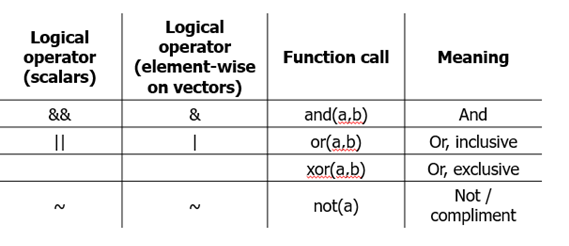

The above operators can be stated as:

- **And**: if both `a` and `b` are `true`, the `a&b` is `true`.

- **Or**: if at least one of `a` and `b` is `true`, then `a|b` is `true`.

- **Xor**: if only one of `a` and `b` is `true`, then `xor(a,b)` is `true`.

- **Not**. If `a` is `true`, then `~a` is `false`. If `a` is `false`, then `~a `is `true`.

The behavior of logical operators can be compactly described in **truth tables**.

            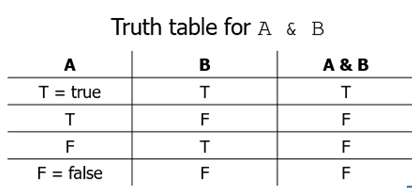

         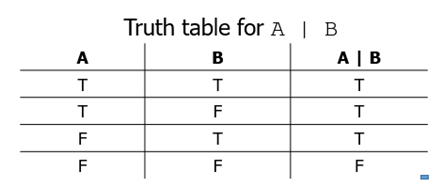

            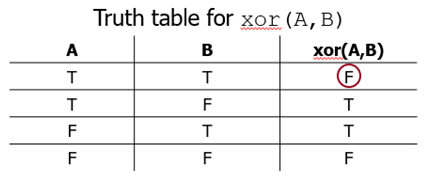

#### Examples: scalars

When the scalar operations are used, the logical operator simply compares the two scalar values and returns `true` (1) or `false` (`0`).

% Examples using And
res1 = (1<2) && (4==5) 

res1 = logical
   0


Alpha = (1<2) && (4<5)

Alpha = logical
   1


% Examples using Or
var_2 = true || false

var_2 = logical
   1


ind = (1<2) || (4==5)

ind = logical
   1


% Examples using xOr
ip = xor(1<2,4<5)

ip = logical
   0


#### Examples: element-wise on vectors

When the element-wise operations are used, the **output is a logical vector** where each entry is a result of the comparison between the values in corresponding indices from the two input vectors.

a = [1,0,0,1]

a =      1     0     0     1


b = [1,1,0,0]

b =      1     1     0     0


a & b

ans = 1×4 logical array
   1   0   0   0


**Note**: when performing element-wise logical operations, be sure to use the correct (single) operators.

#### Precedence revisited

Boolean operators may be combined to yield interesting decisions. Combinations of operators are executed left to right with `and()`** commands having higher precedence than **`or()` commands. An updated precedence table can be seen here.

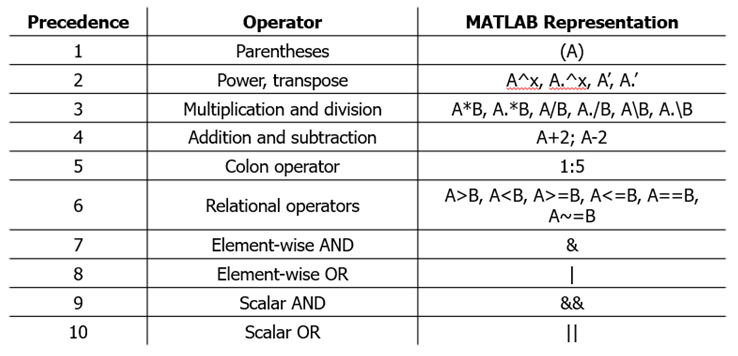

**Example**. Assume variables `a` through `f` represent scalar numbers *(e.g.* `true` or `false`). What will the following code return for each possible combination?

The value of `switchState` as a function of all possible combinations of values `a` through `f` can be represented as a truth table.

            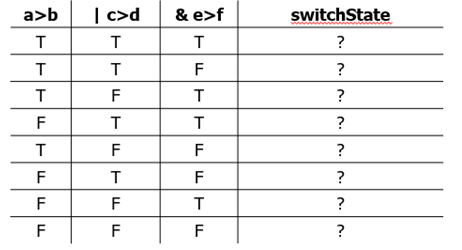

The `and()` operation is performed **first**, based on higher precedence.

            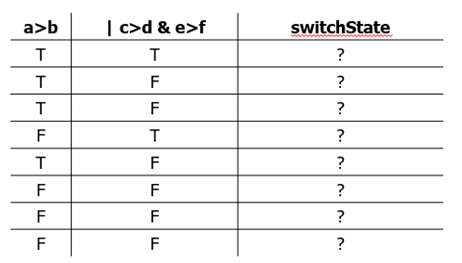

Taking `or()` of column one and then "`and` column" two yields the `switchState` given any combination of inputs `a `through `f`.

            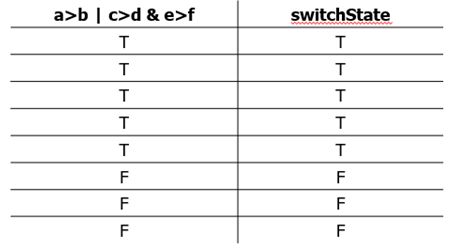

Or, to summarize:

            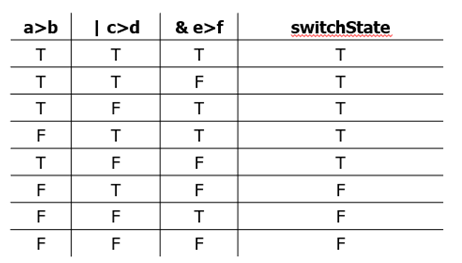

**Example**. 

A = true;
B = false;
C = false;


Due to precedence, the above code is equivalent to the following, which has unnecessary parentheses ...

out 

out = logical
   0


And different from the following, in which precedence has been overriden.

#### Boolean operators and conditional statements

Logical operators may be used to remove nested `if` statements. Consider the example above:

p = 6;
q = 15;
res = NaN;

if p > 5
    if q == 15
        res = p*q;
    end
end
disp(res)

    90



By using a logical operator, we can simplify this code.

if p>5 && q==15
    res = p*q
end

res = 90

disp(res)

    90



**Example**. Consider the following code.

% Declare initial variable
res = false;

a = 15;
b = 20;
c = 30;

% If this condition is true, change the value of res
if a<20 && b==20 || c>20  
    res = true;
end
disp(res)

   1



**Remember**: precedence order is important. The above is read:

- `a < 20 `is `true`, `b == 20` is `true`, `c > 30` is `true`.

- Thus, `(a < 20) `AND` (b == 20)` is `true`

- Thus, (`(a < 20) `AND `(b == 20`)) OR `c>20` is `true`.

#### Logical statements and `while` loops

Logical statements may also be used to continue or stop  `while` loop execution.

% Assign initial values to variables variables
a = 15; 
b = 17;

% As long as AT LEAST ONE of the current values of a or b is greater than
% 5, the loop will continue. That is, the loop will stop when BOTH a and b
% are less than 5.
while a(end)>5 || b(end)>5
    %generates random numbers from 1 to 20 and adds them to the vector.
    
    a(end+1) = randi([1 20]);
    b(end+1) = randi([1 20]);
end


disp([a',b'])

    15    17
    20    14
    20    15
     6     5
    17     9
     9     8
     6     7
    10     4
    10    18
     2    16
    11     2
    14     8
    16    12
     7    19
     7     7
    16     7
     7     6
     2    10
    15     9
     1    19
    14    14
    14     1
     4    17
    18     2
     3    14
     8    15
    16     7
     2     9
    13    11
    11     7
     3    17
    11     7
    14     5
    16     7
    11    18
    12     4
     5    16
    18     2
    20     9
    15    17
     9    10
     9    12
    18     5
    19    11
    13    16
     9    15
     5    16
     8    14
     9    16
    14     3
    13    20
     9    14
    14     2
     9     7
    19    19
    19     5
    19     4
    12     1
    11    14
    20     5
     5     3



With this, we now have some basic 

**Next time**: we will use loops and conditionals to practice solving some problems.